clc
clear

%Parametri motore

Ra = 2.33;
La = 4e-3;
kv = 0.126; kt = kv;
Jtot = 7.77e-4;
B = 1.0051e-05;

va = 33.6;
ia_max = 1.95;
w_max = 244.33;


%Funzione di trasferimento del motore

P_el = tf(1,[La Ra]);
P_mec = tf(1,[Jtot B]);
Ls = kt*series(P_el,P_mec);

M = feedback(Ls,kv)

M =
 
                0.126
  ----------------------------------
  3.108e-06 s^2 + 0.00181 s + 0.0159
 
Continuous-time transfer function.
Model Properties


%Progetto amplificatore e limitatore di corrente

kamp = (va+(20*va/100))/5;

ia_limite = ia_max+20*ia_max/100;
klim = 5/(ia_limite-ia_max);

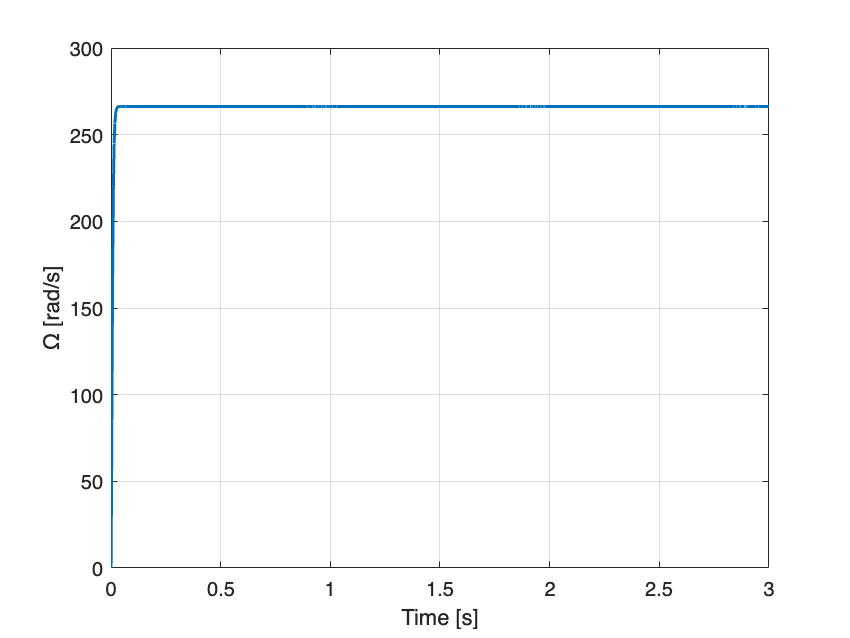

%Plot variabili motore a vuoto
load('motor_vuoto.mat')

plot(w_vuoto.Time, w_vuoto.Data,LineWidth=1.5)
grid on
xlabel("Time [s]")
ylabel("Ω [rad/s]")

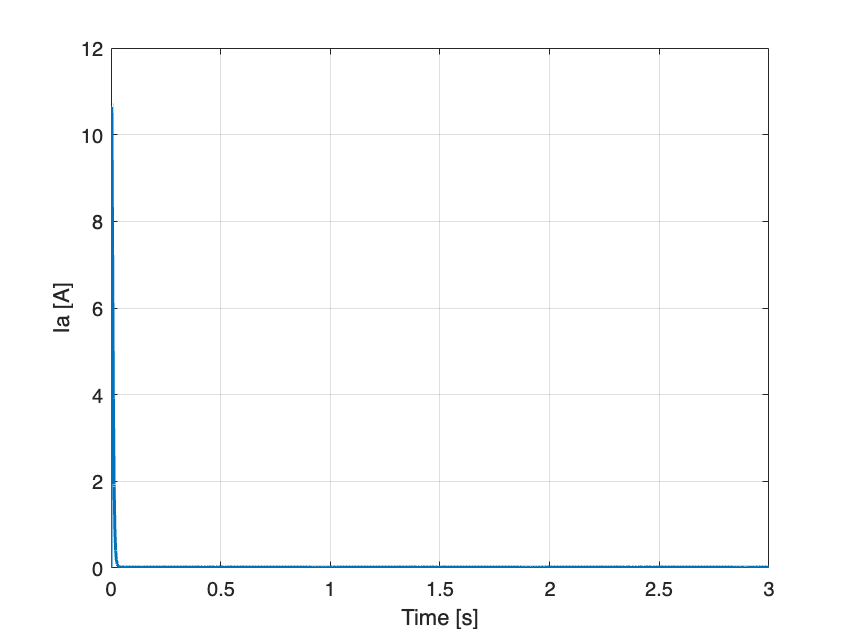



plot(ia_vuoto.Time, ia_vuoto.Data,LineWidth=1.5) 
grid on
xlabel("Time [s]")
ylabel("Ia [A]")

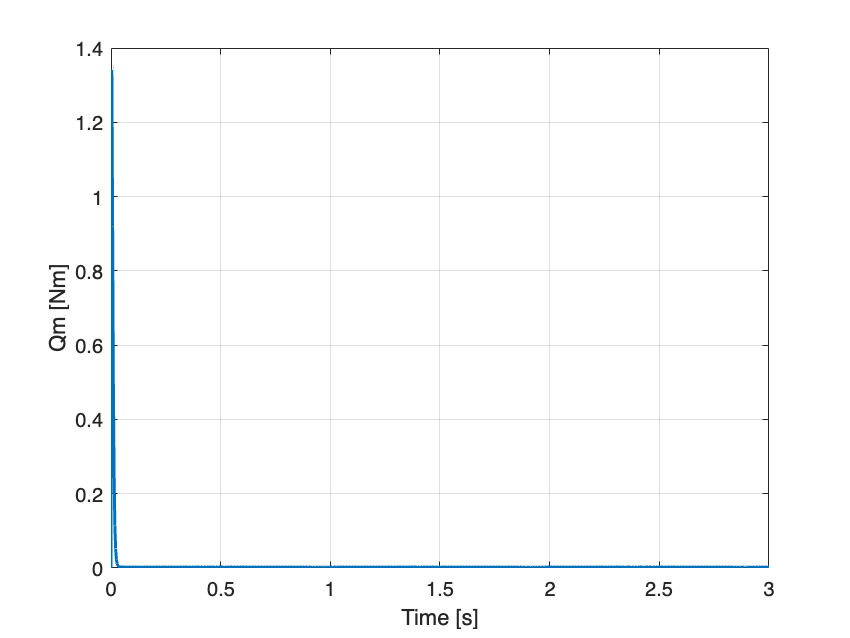



plot(qm_vuoto.Time, qm_vuoto.Data,LineWidth=1.5)
grid on
xlabel("Time [s]")
ylabel("Qm [Nm]")

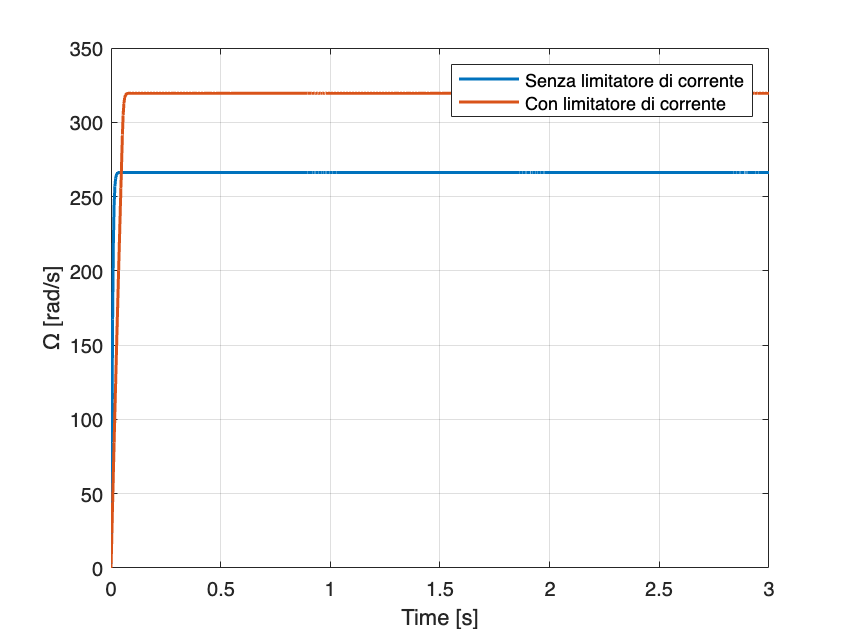

%Grafici di simulazione motore a vuoto e con limitatore di corrente
import motor_vuoto.mat.*

plot(w_vuoto.Time, w_vuoto.Data,LineWidth=1.5) %plot velocità
hold on
plot(out.w.Time, out.w.Data,LineWidth=1.5)
grid on
legend("Senza limitatore di corrente","Con limitatore di corrente")
xlabel("Time [s]")
ylabel("Ω [rad/s]")

hold off

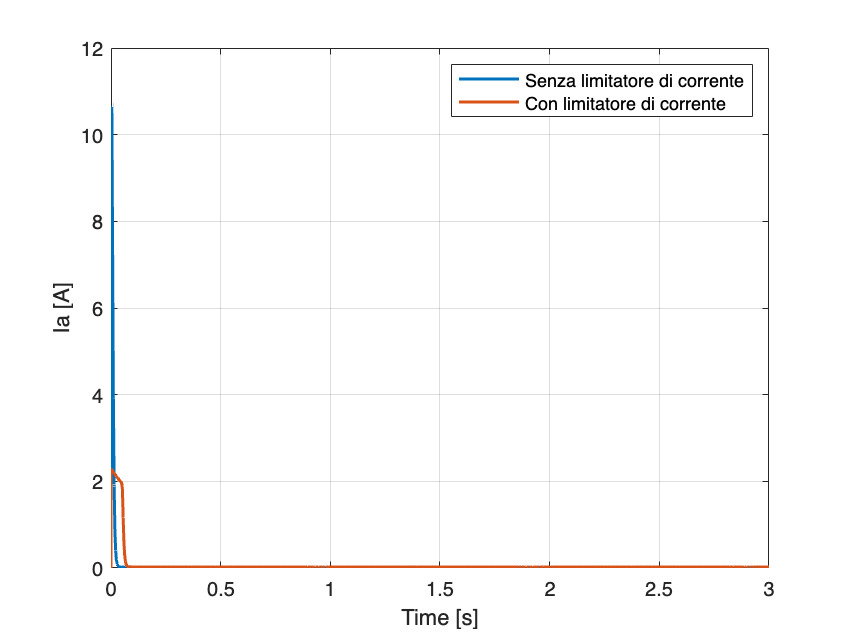


plot(ia_vuoto.Time, ia_vuoto.Data,LineWidth=1.5) %plot corrente di armatura
hold on
plot(out.ia.Time, out.ia.Data,LineWidth=1.5) 
grid on
legend("Senza limitatore di corrente","Con limitatore di corrente")
xlabel("Time [s]")
ylabel("Ia [A]")

hold off

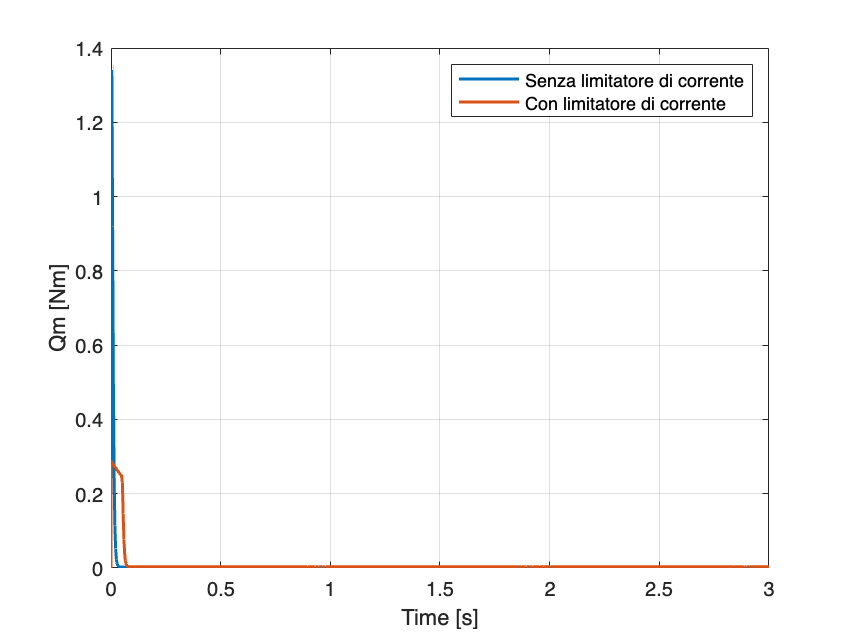


plot(qm_vuoto.Time, qm_vuoto.Data,LineWidth=1.5) %plot coppia motrice
hold on
plot(out.qm.Time, out.qm.Data,LineWidth=1.5)
grid on
legend("Senza limitatore di corrente","Con limitatore di corrente")
xlabel("Time [s]")
ylabel("Qm [Nm]")

hold off

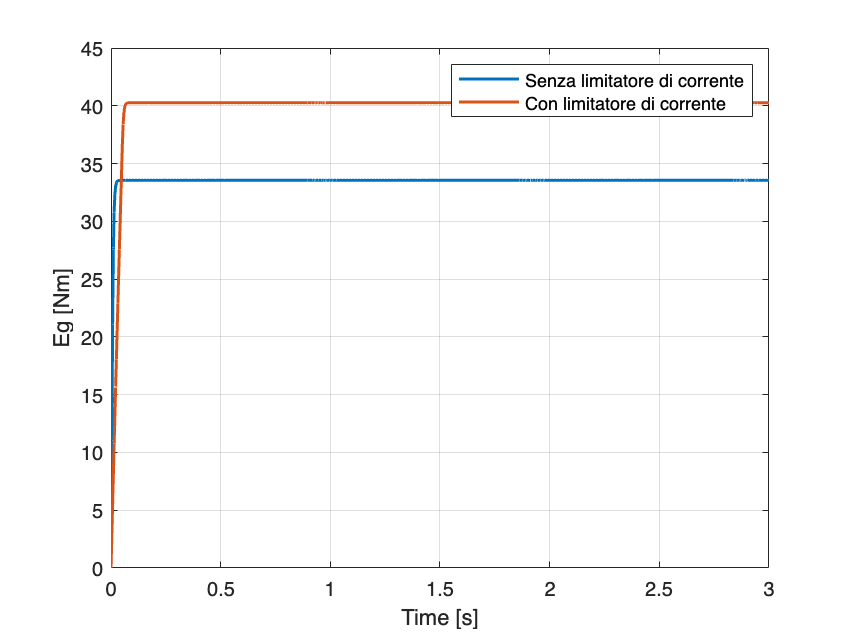


plot(eg_vuoto.Time, eg_vuoto.Data,LineWidth=1.5) %plot eg
hold on
plot(out.eg.Time, out.eg.Data,LineWidth=1.5)
grid on
legend("Senza limitatore di corrente","Con limitatore di corrente")
xlabel("Time [s]")
ylabel("Eg [Nm]")

hold off

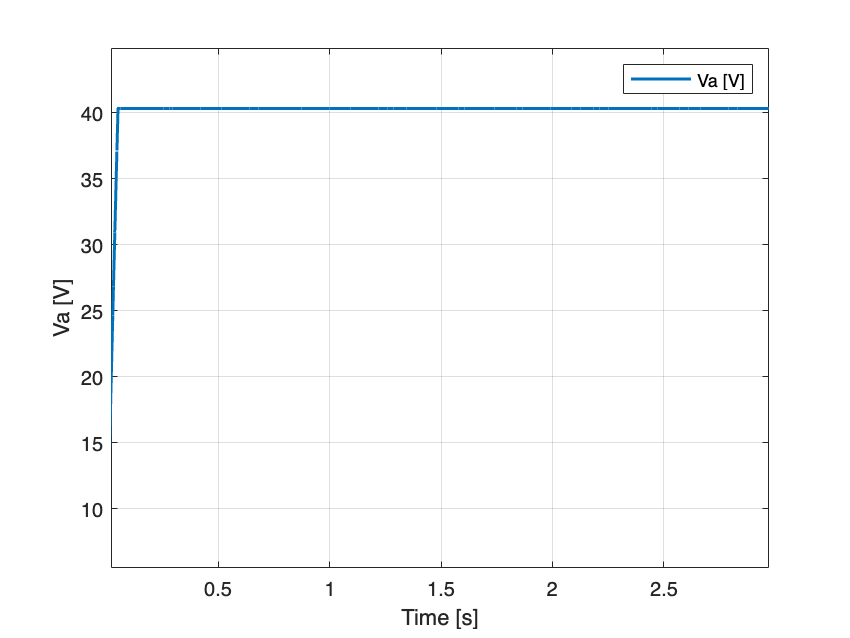

%Grafico Tensione di armatura con amplificatore e limitatore di corrente

plot(out.va_lim.Time, out.va_lim.Data,LineWidth=1.5) %plot tensione di armatura
grid on
legend("Va [V]")
xlabel("Time [s]")
ylabel("Va [V]")
hold off

% Dinamo tachimetrica rumorosa

rv = 3.823; %valore di tensione per cui si ha w desiderato %era 3.85
kdt = rv/w_max; %guadagno di trasduzione del sensore

%% Progetto controllore PI

%Taratura kp
%rif = 3.465
Kp_vec = [3 3.5 4 4.5 5 5.5];
legendcell = cell(1,5);
hold off
for ii=1:length(Kp_vec)
    kp = Kp_vec(ii);
    out = sim("file.slx");
    subplot(2,1,1)
    plot(out.ia.Time, out.ia.Data,LineWidth=1.5)
    hold on
    subplot(2,1,2)
    hold on
    plot(out.w.Time, out.w.Data,LineWidth=0.8)
    legendcell{1,ii} = ['kp = ' num2str(kp)];

end
subplot(2,1,1)
grid on
xlabel("Time [s]")
ylabel("Ia [A]")
legend(legendcell)

subplot(2,1,2)
grid on
xlabel("Time [s]")
ylabel("Ω [rad/s]")
legend(legendcell)

kp = 3.5; %kp scelto per avere un ripple poco più del 5% della corrente di armatura.
out=sim("file.slx")    
plot(out.ia.Time, out.ia.Data,LineWidth=1.5)
grid on
xlabel("Time [s]")
ylabel("Ia [A]")

% Luogo delle radici al variare del parametro Ki, fissato kp
Ki = linspace(50,150,10);

legendcell = cell(1,5);
hold off
for ii=1:length(Ki)
    ki = Ki(ii);
    out = sim("file.slx");
    subplot(2,1,1)
    plot(out.ia.Time, out.ia.Data,LineWidth=0.8)
    hold on
    subplot(2,1,2)
    hold on
    plot(out.w.Time, out.w.Data,LineWidth=0.8)
    legendcell{1,ii} = ['ki = ' num2str(ki)];

end
subplot(2,1,1)
grid on
xlabel("Time [s]")
ylabel("Ia [A]")
legend(legendcell)

subplot(2,1,2)
grid on
xlabel("Time [s]")
ylabel("Ω [rad/s]")
legend(legendcell)

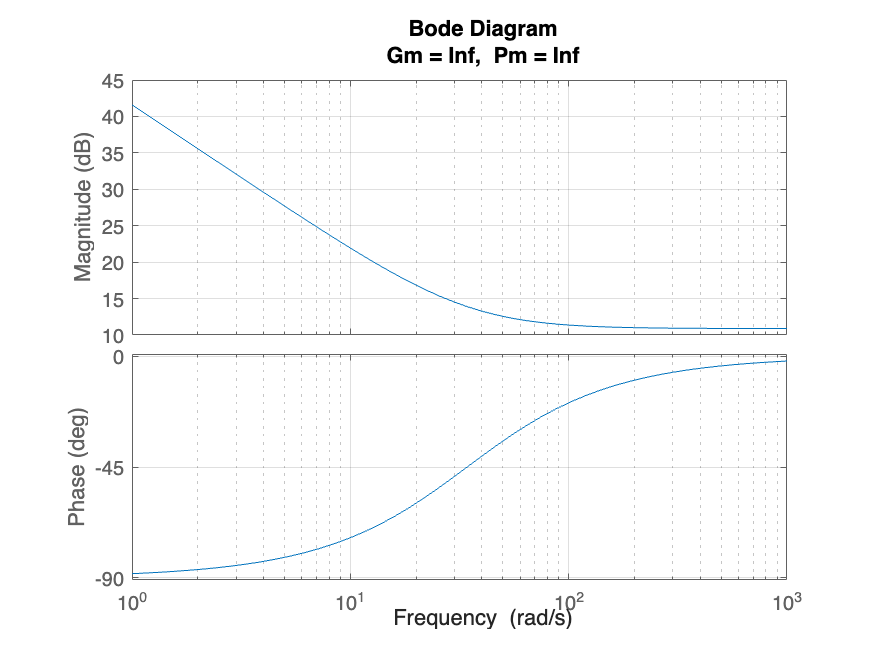

%Plot con controllore PI di progetto

hold off

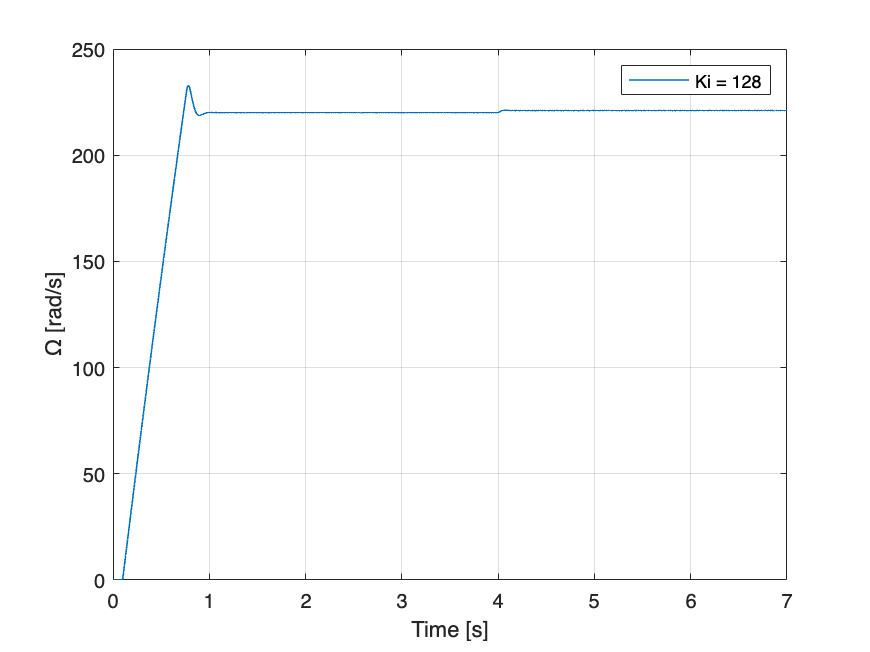

ki = 120; %Ki scelto per avere una sovraelongazione minore del 20%
out = sim("file.slx");
subplot(2,1,1)
plot(out.ia.Time, out.ia.Data,LineWidth=0.8)
hold on
subplot(2,1,2)
hold on
plot(out.w.Time, out.w.Data,LineWidth=0.8)

subplot(2,1,1)
grid on
xlabel("Time [s]")
ylabel("Ia [A]")
subplot(2,1,2)
grid on
xlabel("Time [s]")
ylabel("Ω [rad/s]")

PI =
 
  3.5 s + 120
  -----------
       s
 
Continuous-time transfer function.
Model Properties


T_s = struct with fields:
        Si: [1×1 ss]
        Ti: [1×1 ss]
        Li: [1×1 tf]
        So: [1×1 ss]
        To: [1×1 ss]
        Lo: [1×1 tf]
       PSi: [1×1 ss]
       CSo: [1×1 ss]
     Poles: [3×1 double]
    Stable: 1


T_s =
 
  A = 
           x1      x2      x3
   x1  -582.5  -359.7   -9591
   x2      64       0       0
   x3       0       1       0
 
  B = 
         du
   x1  1024
   x2     0
   x3     0
 
  C = 
           x1      x2      x3
   uC       0  0.2732   9.366
 
  D = 
       du
   uC   0
 
Continuous-time state-space model.


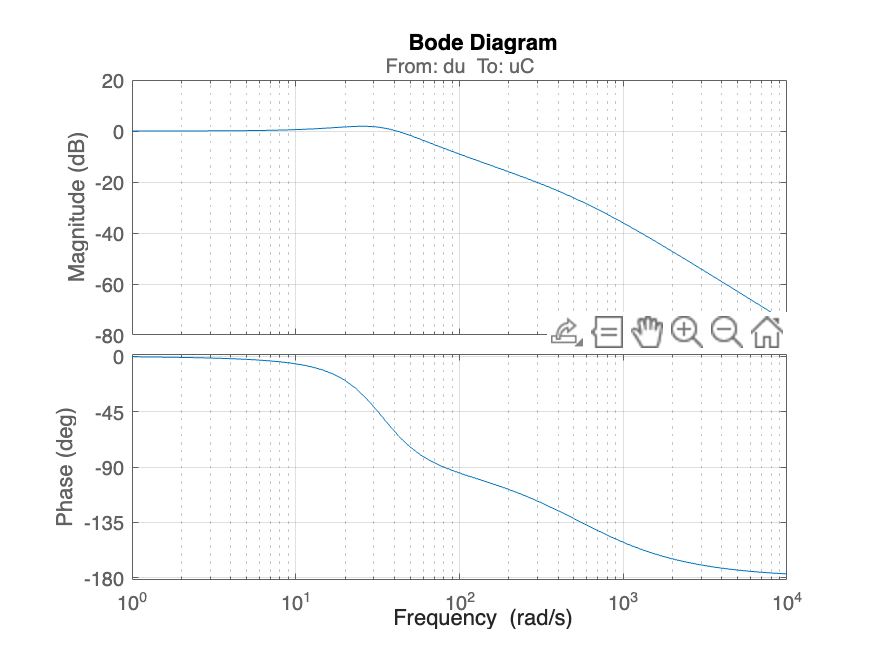


 %%Bode PI+Motore
PI = tf([kp ki], [1 0]);
L = kamp*series(PI, M); 
T_s = L/(1+kdt*L);

figure, margin(T_s)    %luogo delle radici
grid on


%% Nichols
nichols(T_s)
ngrid

% Progetto guadagno feed forward

kff = kv/(kamp*kdt);
S_new = ia_max*Ra/kamp

S_new = 0.5634

S_new2 = S_new + 20*S_new/100;

% Progetto rampa
Qmax = 0.1519; %coppia motrice massima
dw_dt = Qmax/Jtot; %fisso l'accelerazione massima

% Progetto profilo di accelerazione/velocità/posizione
x0 = 0;
xf = 5;

v_max = 1;
a_max = 0.8;

Ts = v_max/a_max; % tempo di salita
s_Ts = 1/2*a_max*Ts^2; % spazio percorso durante il tempo di salita

Td = Ts; % tempo di discesa
s_Td = s_Ts; % spazio percorso durante il tempo di discesa

s_regime = (xf-x0)-(s_Ts+s_Td);
T_regime = s_regime/v_max;

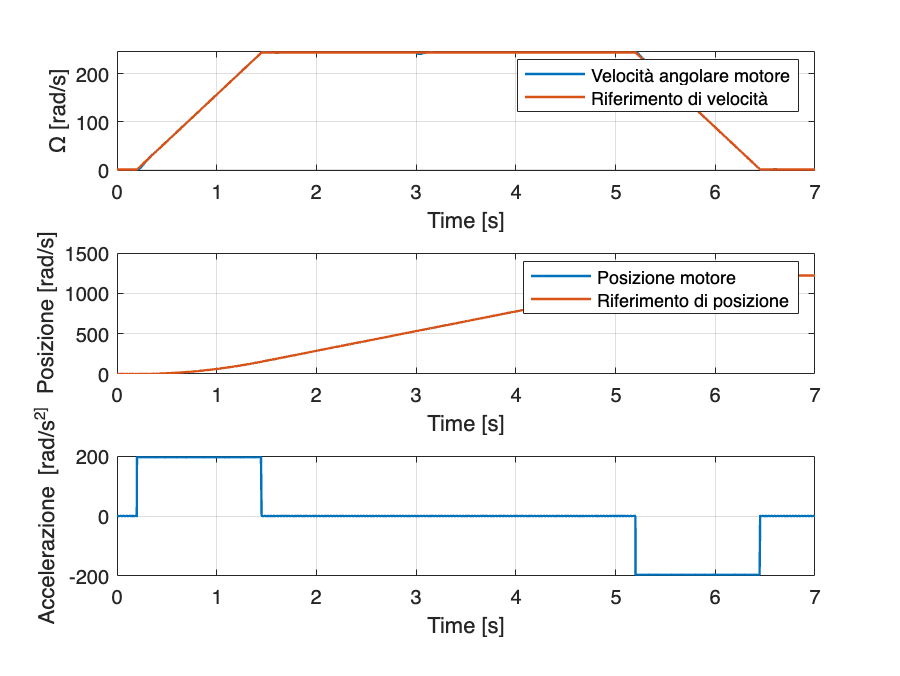

%%Costruzione plot finali
subplot(2,1,1)
plot(out.w.Time, out.w.Data,LineWidth=1.2)
hold on
plot(out.w_rif.Time, out.w_rif.Data,LineWidth=1.2)
grid on
xlabel("Time [s]")
ylabel("Ω [rad/s]")
legend("Velocità angolare motore","Riferimento di velocità");

subplot(2,1,2)
plot(out.pos.Time, out.pos.Data,LineWidth=1.2)
hold on
plot(out.pos_rif.Time, out.pos_rif.Data,LineWidth=1.2)
grid on
xlabel("Time [s]")
ylabel("Posizione [rad/s]")
legend("Posizione motore","Riferimento di posizione");
% 
% subplot(3,1,3)
% plot(out.acc_rif.Time, out.acc_rif.Data,LineWidth=1.2)
% grid on
% xlabel("Time [s]")
% ylabel("Accelerazione [rad/s^2]")

fdt_ciclochiuso =
 
                   1.105e-05 s^4 + 0.006817 s^3 + 0.2773 s^2 + 1.939 s
  --------------------------------------------------------------------------------------
  9.66e-12 s^6 + 1.125e-08 s^5 + 3.55e-06 s^4 + 0.0001642 s^3 + 0.004591 s^2 + 0.03033 s
 
Continuous-time transfer function.
Model Properties